Questo progetto riguarda l'identificazione di un segnale estratto da un dataset presente sul sito *PhysioNet *al seguente link: [https://physionet.org/content/bidmc/1.0.0/](https://physionet.org/content/bidmc/1.0.0/)

Il dataset di cui sopra contiene i dati relativi a 53 pazienti affetti da patologie respiratorie. Per ciascun paziente, il dataset contiene vari segnali biomedici. Il segnale di interesse è rappresentato da un segnale fotopletismografico misurato mediante saturimetro in un intervallo di tempo di 8 minuti.

L'obiettivo del progetto è realizzare un modello AR che rilevi le finestre temporali in cui il paziente va incontro ad una crisi respiratoria. 

Nel seguente script il modello viene testato su un solo paziente, ma può essere iterato per ogni paziente. 

close all
clear
clc

Caricamento del dataset 

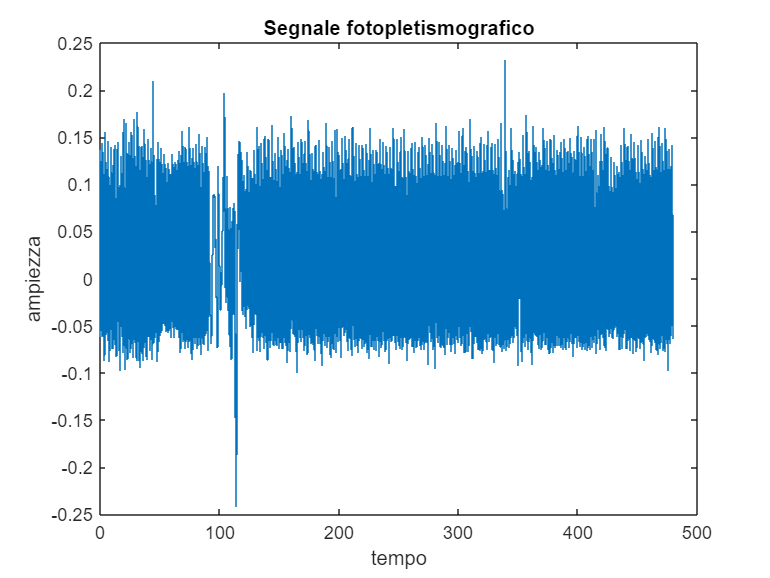

filename = 'bidmc_data.mat';
dataset = load(filename);
%Dopo aver caricato il dataset, si estraggono i dati al relativi al primo
%paziente e si prende in esame il segnale fotopletismografico (ppg)
paziente = dataset.data(1).ppg;
%Si estraggono dall'oggetto paziente gli attributi relativi ai valori del
%segnale campionato (v) e alla frequenza di campionamento (fs)
ppg = paziente.v;
fs = paziente.fs;
%Poichè il segnale non è a media nulla, si effettua un detrend 
ppg = detrend(ppg,0);
%Per poter visualizzare il segnale, si costruisce l'asse dei tempi
t = [1:length(ppg)]/fs;
figure
stairs(t,ppg)
xlabel('tempo')  
ylabel('ampiezza')
title('Segnale fotopletismografico')

Sottocampionamento del segnale 

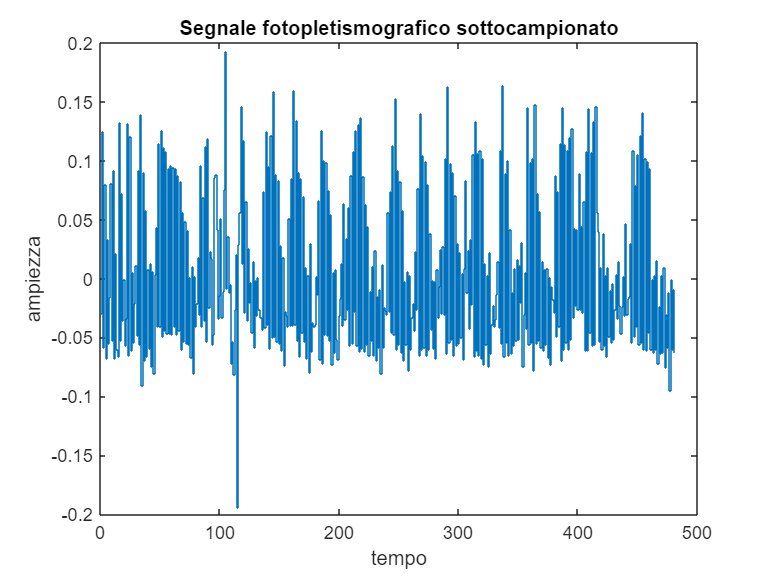

%L'obiettivo del sottocampionamento è duplice: da un lato migliora la
%visualizzazione grafica del segnale e dall'altro effettua un filtraggio
%del segnale. Ponenendo il fattore di scala pari alla frequenza di
%campionamento si ottiene una nuova frequenza di campionamento di 1 Hz,
%che realizza i vantaggi di cui sopra. 
fattore = fs;
ppg = downsample(ppg,fattore);
fs = fs/fattore;
%Si costruisce l'asse dei tempi con la nuova frequenza di campionamento
t = [1:length(ppg)]/fs; 
figure
stairs(t,ppg)
xlabel('tempo')  
ylabel('ampiezza')
title('Segnale fotopletismografico sottocampionato')

%Dal grafico si deduce che il segnale presenta un fronte di salita seguito
%da un fronte di discesa in finestre temporali di lunghezza non omogenea.
%Un unico modello AR non è in grado di discriminare i due diversi andamenti.
%Si rende necessario quindi addestrare un modello AR che identifichi i
%fronti di salita e un altro modello AR che invece identifichi i fronti di
%discesa. Per discriminare le finestre temporali in cui il segnale presenta
%un fronte di salita da quelle in cui il segnale presenta un fronte di
%discesa, si rende necessario individuare i punti di massimo e di minimo
%del segnale in ciascuna finestra temporale.

Individuazione del vettore dei massimi 

%Le seguenti istruzioni servono ad individuare i punti di massimo del
%segnale.
%Ad ogni iterazione si calcola il massimo in una data finestra con
%sufficientemente pochi campioni, il valore ottenuto viene confrontato con
%il massimo della finestra precedente: se il valore precedente è più
%grande allora viene memorizzato nel vettore dei massimi; in caso
%contrario si itera il processo.
L = 5;
n_campioni = length(ppg);
i = 1;
massimi = [];%Vettore dei massimi
id_massimi = [];%Indici del vettore dei massimi
rif_massimo = 0;%Valore massimo di riferimento  
while i+L-1 <= n_campioni
    [massimo,id] = max(ppg(i:(i+L-1)));
    if massimo >= rif_massimo;
        rif_massimo = massimo;
        id_rif = id;%Indice del massimo di riferimento nella finestra
    else
    massimi = [massimi,rif_massimo];
    rif_tmp = id_rif+i-L-1;%Indice del massimo di riferimento nell'asse dei tempi
    id_massimi = [id_massimi, rif_tmp];
    rif_massimo = 0;
    end
    i = i+L;
end 

Individuazione del vettore dei minimi 

%Le seguenti istruzioni servono ad individuare i punti di minimo del
%segnale.
%Ad ogni iterazione si calcola il minimo in una data finestra con
%sufficientemente pochi campioni, il valore ottenuto viene confrontato con
%il minimo della finestra precedente: se il valore precedente è più
%piccolo allora viene memorizzato nel vettore dei minimi; in caso
%contrario si itera il processo.
L =5;
n_campioni = length(ppg);
i = 1;
minimi = [];%Vettore dei minimi
id_minimi = [];%Indici del vettore dei minimi
rif_minimo = 0;%Valore minimo di riferimento
while i+L-1 <= n_campioni
    [minimo,id] = min(ppg(i:(i+L-1)));
    if minimo <= rif_minimo; 
        rif_minimo = minimo;
        id_rif = id;%Indice del minimo di riferimento nella finestra
    else
    minimi = [minimi,rif_minimo];
    rif_tmp = id_rif+i-L-1;%Indice del minimo di riferimento nell'asse dei tempi
    id_minimi = [id_minimi, rif_tmp];
    rif_minimo = 0;
    end
    i = i+L;
end  

%Per poter addestrare il modello è necessario individuare un training set,
%corrispondente a una finestra di campioni in cui il comportamento è
%normale. Quest'ultima è stata individuata graficamente, prendendo in
%considerazione una finestra in cui il segnale non presenta anomalie. 
%Il comportamento normale consiste nell'alternanza di un fronte di salita
%(che inizia con un punto di minimo e termina con un punto di massimo)
%e un fronte di discesa (che inizia con un punto di massimo e termina con
%un punto di minimo). Invece, quando avviene una crisi respiratoria,
%questa alternanza potrebbe essere non rispettata. Pertanto, per
%individuare i validation set, si utilizzano delle finestre che hanno la
%stessa lunghezza del training set. I punti di inizio di
%queste finestre sono i valori contenuti nel vettore dei minimi per
%quanto riguarda i fronti di salita e i valori contenuti nel vettore dei
%massimi per quanto riguarda i fronti di discesa. 

Calcolo dell'ordine ottimo del modello AR dei fronti di discesa 

%Estrazione del training set individuato graficamente
start_t = id_massimi(11);%inizio del training set
end_t = id_minimi(13);%fine del training set 
train = ppg(start_t:end_t);%training set 
L = length(train);%lunghezza finestra 
%Per calcolare l'ordine ottimo del modello AR, si estrae graficamente 
%un validation set che non presenta anomalie
start_v = id_massimi(12);%inizio del validation set
end_v = start_v + L;%fine del validation set 
valid = ppg(start_v:end_v);%validation set
tot = [train',valid'];%vettore contenente training set e validation set
tot = tot';
N = length(tot);
Ord_Max = 4; 
for k = 1:Ord_Max
    m = ar(train,k);%modello AR 
    ep = pe(m,tot);%calcolo errore di predizione
    %Calcolo degli indici di aderenza
    JPT(k) = cov(ep(1:L));
    JPV(k) = cov(ep(L+1:N));
    %Calcolo degli indici surrogati
    Jfpe(k) = fpe(m);
    Jaic(k) = aic(m);
    n = 2*k;
    Jmdl(k) = log(L)*n/L + log(JPT(k));  
end
x = 2:2:2*Ord_Max;%vettore degli ordini
[minimo, id] = min(Jmdl);%calcolo del minimo dell'indice Jmdl 
ordine = x(id);%ordine ottimo estratto dal vettore degli ordini
md = ar(train,ordine);%modello AR dei fronti di discesa 

Modello AR dei fronti di discesa 

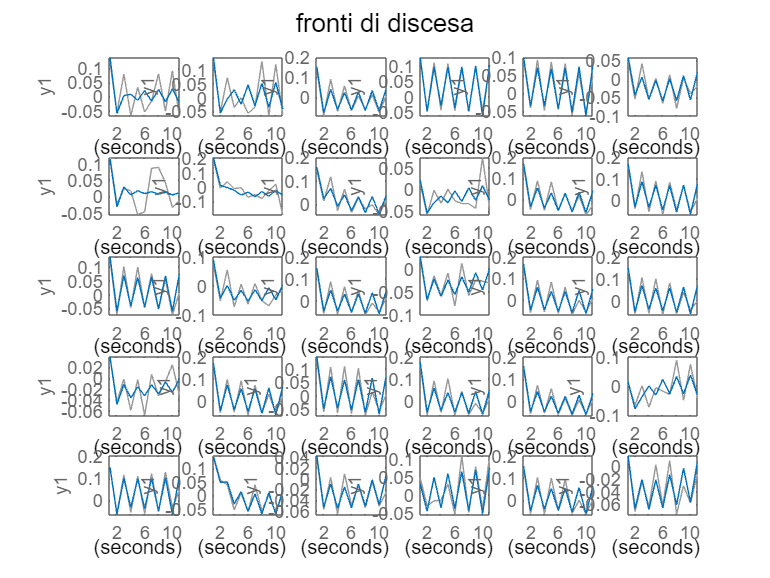

%Si  applica il modello AR a tutte le finestre del segnale per valutarne il
%fit al fine di individuare le finestre in cui il comportamento è normale
%(fit relativamente alto) e quelle in cui sono presenti anomalie (fit 
%relativamente basso)
figure
for i = 1:(length(id_massimi)-1)
    start_v = id_massimi(i);
    end_v = start_v+L;
    valid = ppg(start_v:end_v); 
    subplot(5,6,i)
    compare(md, valid)
    xlabel('')  
    ylabel('')
    title('')
    legend('off')
end 
sgtitle('fronti di discesa')

Finestre rappresentative dei fronti di discesa

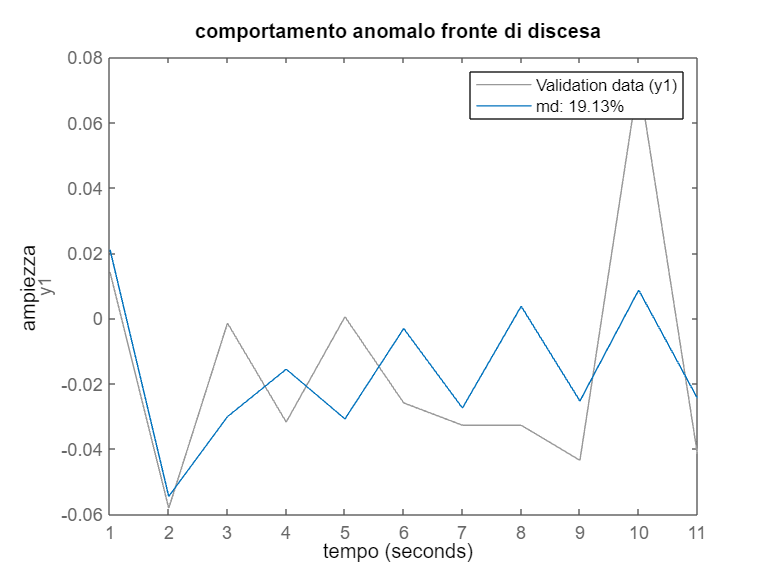

%Per una maggiore chiarezza grafica, di seguito si riportano due finestre
%rispettivamente rappresentative del comportamento anomalo e normale
start_v = id_massimi(10);%finestra con comportamento anomalo
end_v = start_v+L;
valid = ppg(start_v:end_v);
figure
compare(md, valid)
xlabel('tempo')  
ylabel('ampiezza')
title('comportamento anomalo fronte di discesa')

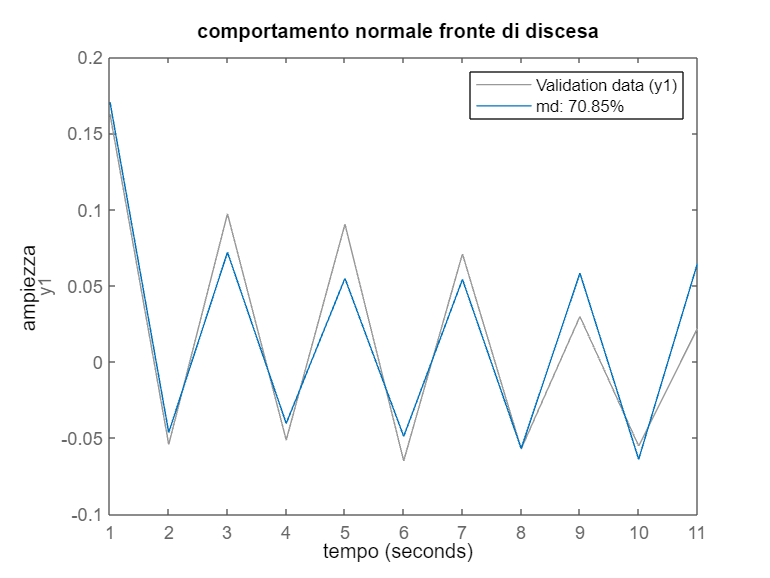


start_v = id_massimi(20);%finestra con comportamento normale 
end_v = start_v+L;
valid = ppg(start_v:end_v);
figure
compare(md, valid)
xlabel('tempo')  
ylabel('ampiezza')
title('comportamento normale fronte di discesa')

Calcolo dell'ordine ottimo del modello AR dei fronti di salita 

%Estrazione del training set individuato graficamente
start_t = id_minimi(13);%inizio del training set
end_t = id_massimi(12);%fine del training set 
train = ppg(start_t:end_t);%training set 
L = length(train);%lunghezza finestra 
%Per calcolare l'ordine ottimo del modello AR, si estrae graficamente 
%un validation set che non presenta anomalie
start_v = id_minimi(14);%inizio del validation set
end_v = start_v+L;%fine del validation set 
valid = ppg(start_v:end_v);%validation set
tot = [train',valid'];%vettore contenente training set e validation set
tot = tot';
N = length(tot);
Ord_Max = 4; 
for k = 1:Ord_Max
    m = ar(train,k);%modello AR 
    ep = pe(m,tot);%calcolo errore di predizione
    %Calcolo degli indici di aderenza
    JPT(k) = cov(ep(1:L));
    JPV(k) = cov(ep(L+1:N));
    %Calcolo degli indici surrogati
    Jfpe(k) = fpe(m);
    Jaic(k) = aic(m);
    n = 2*k;
    Jmdl(k) = log(L)*n/L + log(JPT(k));  
end
x = 2:2:2*Ord_Max;%vettore degli ordini
[minimo, id] = min(Jmdl);%calcolo del minimo dell'indice Jmdl 
ordine = x(id);%ordine ottimo estratto dal vettore degli ordini
ms = ar(train,ordine);%modello AR dei fronti di salita

Modello AR dei fronti di salita 

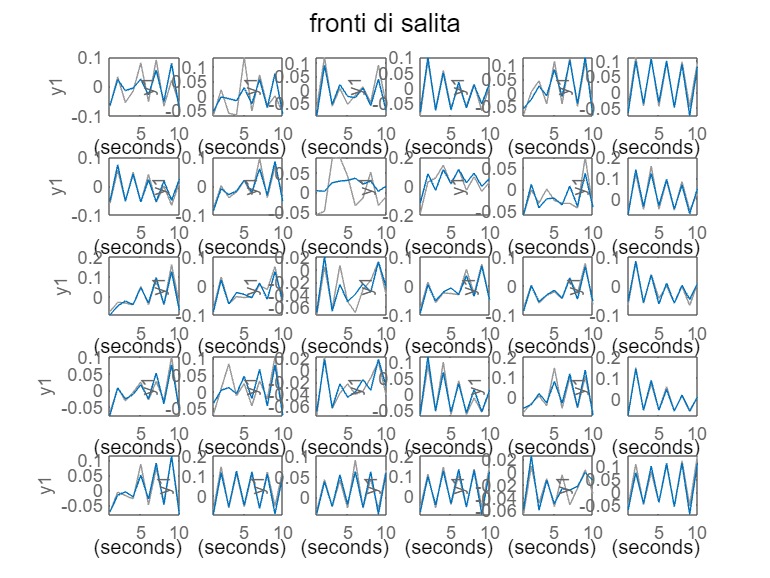

%Si  applica il modello AR a tutte le finestre del segnale per valutarne il
%fit al fine di individuare le finestre in cui il comportamento è normale
%(fit relativamente alto) e quelle in cui sono presenti anomalie (fit 
%relativamente basso)
figure
for i = 1:(length(id_minimi))
    start_v = id_minimi(i);
    end_v = start_v+L;
    valid = ppg(start_v:end_v); 
    subplot(5,6,i)
    compare(ms, valid)
    xlabel('')  
    ylabel('')
    title('')
    legend('off')
end 
sgtitle('fronti di salita')

Finestre rappresentative dei fronti di salita

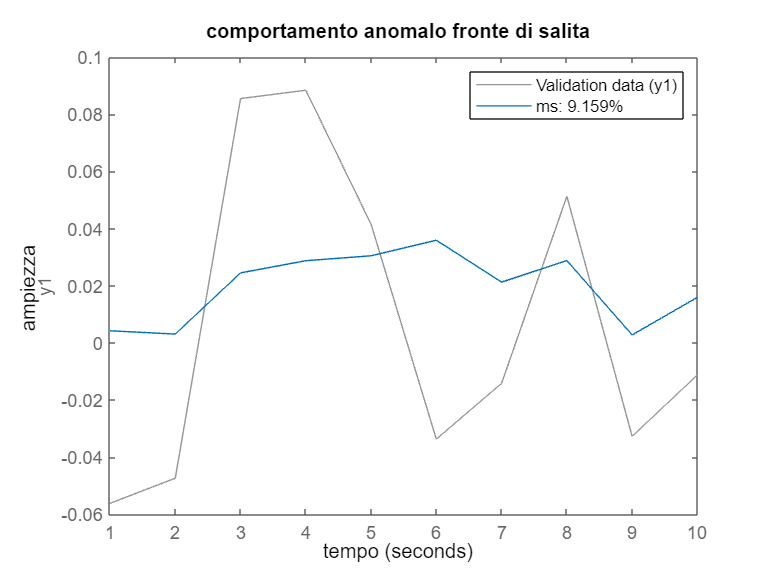

%Per una maggiore chiarezza grafica, di seguito si riportano due finestre
%rispettivamente rappresentative del comportamento anomalo e normale
start_v = id_minimi(9);%finestra con comportamento anomalo
end_v = start_v+L;
valid = ppg(start_v:end_v);
figure
compare(ms, valid)
xlabel('tempo')  
ylabel('ampiezza')
title('comportamento anomalo fronte di salita')

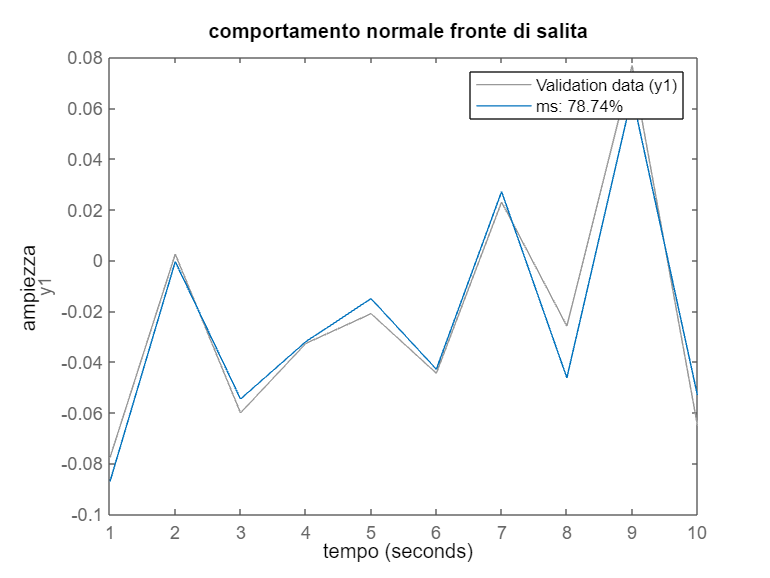


start_v = id_minimi(17);%finestra con comportamento normale 
end_v = start_v+L;
valid = ppg(start_v:end_v);
figure
compare(ms, valid)
xlabel('tempo')  
ylabel('ampiezza')
title('comportamento normale fronte di salita')

Lo script di cui sopra può essere migliorato per realizzare il monitoraggio di pazienti affetti da patologie respiratorie. Per raggiungere tale obiettivo, sarebbe necessario inserire uno switch logico che selezioni quale dei due modelli AR applicare, in modo da ottenere il fit e quindi poter individuare in tempo reale eventuali anomalie respiratorie. 